clear; close all; clc;
layout_file = keyboard_importer("C:\Users\$user\MATLAB Drive\Keyboard_Analysis\keyboard_layouts_en\qwerty.txt", [1, Inf]);
[layout, data] = compile(layout_file)

ans = 20×2 table
          SFB     dSFB
          ____    ____

    'a      93    1479
    ;a      13     288
    ,o     507    2990
    qo       7     111
    .e    4716    3925
    je     319     368
    pu    2679     866
    ku      84     892
    yi     581    2559
    xi     504      88
    fd      30    1797
    bd      50    2493
    gh    4090     822
    mh      78    3205
    ct    3279    2983
    wt     810    6328


bigrams = 20×2 table
          SFB     dSFB
          ____    ____

    .e    4716    3925
    gh    4090     822
    ct    3279    2983
    pu    2679     866
    ls    1885    6397
    rn    1684    5644
    wt     810    6328
    yi     581    2559
    ,o     507    2990
    xi     504      88
    vn     396    3040
    je     319     368
    'a      93    1479
    ku      84     892
    mh      78    3205
    bd      50    2493


ans = 15×2 table
    left_pat    left_count
    ________    __________

      "'"            13069
      "a"       1.1489e+05
      ";"             1559
      ","            21630
      "o"       1.2177e+05
      "q"             1102
      "."            24484
      "e"       1.8318e+05
      "j"             2361
      "p"            24237
      "u"            47825
      "k"            14709
      "y"            39332
      "i"       1.0562e+05
      "x"             1990


ans = 15×2 table
    right_pat    right_count
    _________    ___________

       "f"            30950 
       "d"            55315 
       "b"            23142 
       "g"            31834 
       "h"            80517 
       "m"            39345 
       "c"            34664 
       "t"       1.3879e+05 
       "w"            35703 
       "r"            82198 
       "n"       1.0408e+05 
       "v"            16235 
       "l"            62850 
       "s"            90589 
       "z"             1147 


ans = 30×2 table
    letter     percent  
    ______    __________

     "'"       0.0084583
     "a"        0.074356
     ";"        0.001009
     ","        0.013999
     "o"        0.078812
     "q"      0.00071322
     "."        0.015846
     "e"         0.11855
     "j"        0.001528
     "p"        0.015686
     "u"        0.030952
     "k"       0.0095197
     "y"        0.025456
     "i"        0.068358
     "x"       0.0012879
     "f"        0.020031


ans = 6×4 table
    lateral_SFB_disp    diag_1u_SFB_count    lateral_dSFB_disp    diag_1u_dSFB_count
    ________________    _________________    _________________    __________________

          "py"                 391                 "py"                  1214       
          "ui"                1084                 "ui"                  2943       
          "kx"                   0                 "kx"                     1       
          "fg"                  17                 "fh"                   923       
          "dh"                  54                 "dh"                  2838       
          "bm"                 898                 "bh"                   315       


ans = 10×3 table
    SFB_2u_disp    SFB_2u    dSFB_2u
    ___________    ______    _______

       "';"           13        13  
       ",q"           16        16  
       ".j"          139       139  
       "pk"          164       164  
       "yx"           35        35  
       "fb"          661       661  
       "gm"         1462      1462  
       "cw"          278       278  
       "rv"         5372      5372  
       "lz"          300       300  


ans = 8×3 table
    diag_1u_disp    diag_1u_SFB_count    diag_1u_dSFB_count
    ____________    _________________    __________________

        "pi"              2006                  2723       
        "uy"               226                 11850       
        "ux"                30                    27       
        "ki"              3512                  2327       
        "fh"                16                   963       
        "dg"               272                  1234       
        "dm"                77                  2833       
        "bh"                42                   412       


ans = 4×3 table
    diag_2u_disp    diag_2u_SFB_count    diag_2u_dSFB_count
    ____________    _________________    __________________

        "px"               261                  575        
        "ky"               447                   18        
        "fm"                 8                  861        
        "bg"                80                  906        


layout = 3×10 string array
    "'"    ","    "."    "p"    "y"    "f"    "g"    "c"    "r"    "l"
    "a"    "o"    "e"    "u"    "i"    "d"    "h"    "t"    "n"    "s"
    ";"    "q"    "j"    "k"    "x"    "b"    "m"    "w"    "v"    "z"


data =        0.00845828651903551        0.0139989851868344        0.0158461004768586        0.0156862415151782        0.0254557598413578        0.0200309103806067        0.0206030371908315        0.0224346196262795        0.0531987325190666        0.0406766629215228
        0.0743557748564505        0.0788124097152828         0.118551923744039        0.0309524487545239        0.0683575041809267        0.0357999937868582        0.0521107854964559        0.0898239092052874        0.0673601654766774        0.0586294068002837
       0.00100898834518145      0.000713216905958921        0.0015280445689374       0.00951969824841177       0.00128793252527972        0.0149775550251373        0.0254641734709199        0.0231070627889758        0.0105073289185509      0.000742341008289367


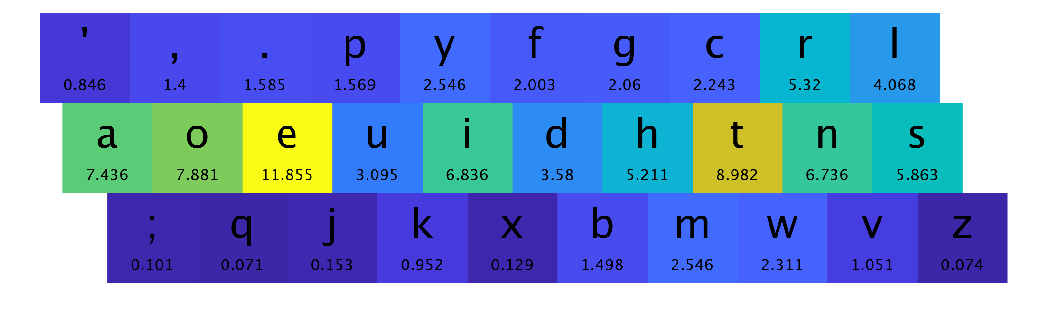

I = image_maker(layout,data);
imshow(I)